%%Compare pfammatter events to bergstrom events

fs = 512;

for k = [1:21 25:72]
    
    tot = SigSumm(k).totRecordLength;
    
%pull pfammatter events from dataFrame (originally in datpoints)
    
    a = dataFrame(k).starts;
    a = a';
    b = dataFrame(k).ends;
    b = b';
    evJP = [a b]/fs;

    clear a b;
    
%pull bergstrom events from SigSumm (originally in seconds)
  
    a1 = SigSumm(k).spike;
    a2 = SigSumm(k).seizure;
    a3 = SigSumm(k).abnormal;
    
    evRB = [a1; a2; a3];
    %evRB = evRB;%*fs;

 %expand all events 
    
    [m, ~] = size(evJP);
    [n, ~] = size(evRB);
 
    for mm = 1:m
        
        if mm == 1
        h = 0;
        else end
        
        SZ = floor(evJP(mm,1)):floor(evJP(mm,2));
        add = length(SZ);
        
        hh = h+1; 
        hj = h+add;
        
        jpEvent(hh:hj,1) = SZ';
        
        h = length(jpEvent);
        
        clear SZ hh
    end

    clear h
    
    for mm = 1:n
        
        if mm == 1
        h = 0;
        else end
        
        SZ = floor(evRB(mm,1)):floor(evRB(mm,2));
        add = length(SZ);
        
        hh = h+1; 
        hj = h+add;
        
        rbEvent(hh:hj,1) = SZ';
        
        h = length(rbEvent);
        
        clear SZ
    end
    

    evAgree = intersect(jpEvent,rbEvent);
    TP_SZ = length(evAgree);
    FN_SZ = length(rbEvent) - TP_SZ;
    FP_SZ = length(jpEvent) - TP_SZ;
    TN_SZ = tot - (TP_SZ+FN_SZ+FP_SZ);
    
    confMat = [TP_SZ FN_SZ;FP_SZ TN_SZ];
    TPR = TP_SZ/(TP_SZ+FN_SZ);
    FPR = FP_SZ/(TN_SZ+FP_SZ);
    
    rocDataAll(k).file = SigSumm(k).fileID;
    rocDataAll(k).evType = 'all';
    rocDataAll(k).confMatrix = confMat;
    rocDataAll(k).TPR = TPR;
    rocDataAll(k).FPR = FPR;
    rocDataAll(k).SF = 4.0;

    clear a1 a2 a3 add evAgree evJP evRB h hh hj jpEvent rbEvent...
    FN_SZ FP_SZ FPR TPR TP_SZ TN_SZ tot confMat m mm n tot
    
end



for k = [1:21 25:72]
        
    tot = SigSumm(k).totRecordLength;
    
%pull pfammatter events from dataFrame (originally in datpoints)
    
    a = dataFrame(k).starts;
    a = a';
    b = dataFrame(k).ends;
    b = b';
    evJP = [a b]/fs;

    clear a b;
    
%pull bergstrom events from SigSumm (originally in seconds)
  
    a1 = SigSumm(k).spike;
    %a2 = SigSumm(k).seizure;
    %a3 = SigSumm(k).abnormal;
    
    evRB = a1; %[a1; a2; a3];
    evRB = evRB;%*fs;

 %expand all events 
    
    [m ~] = size(evJP);
    [n ~] = size(evRB);
 
    for mm = 1:m
        
        if mm == 1
        h = 0;
        else end
        
        SZ = floor(evJP(mm,1)):floor(evJP(mm,2));
        add = length(SZ);
        
        hh = h+1; 
        hj = h+add;
        
        jpEvent(hh:hj,1) = SZ';
        
        h = length(jpEvent);
        
        clear SZ hh
    end

    clear h
    
    if isempty(evRB)==1
        rbEvent = [0];
    else 
    
    for mm = 1:n
        
        if mm == 1
        h = 0;
        else end
        
        SZ = floor(evRB(mm,1)):floor(evRB(mm,2));
        add = length(SZ);
        
        hh = h+1; 
        hj = h+add;
        
        rbEvent(hh:hj,1) = SZ';
        
        h = length(rbEvent);
        
        clear SZ
    end
     
    end

    evAgree = intersect(jpEvent,rbEvent);
    TP_SZ = length(evAgree);
    FN_SZ = length(rbEvent) - TP_SZ;
    FP_SZ = length(jpEvent) - TP_SZ;
    TN_SZ = tot - (TP_SZ+FN_SZ+FP_SZ);
    
    confMat = [TP_SZ FN_SZ;FP_SZ TN_SZ];
    TPR = TP_SZ/(TP_SZ+FN_SZ);
    FPR = FP_SZ/(TN_SZ+FP_SZ);
    
    rocDataSP(k).file = SigSumm(k).fileID;
    rocDataSP(k).evType = 'spikes';
    rocDataSP(k).confMatrix = confMat;
    rocDataSP(k).TPR = TPR;
    rocDataSP(k).FPR = FPR;
    rocDataSP(k).SF = 4.0;

    clear a1 a2 a3 add evAgree evJP evRB h hh hj jpEvent rbEvent...
    FN_SZ FP_SZ FPR TPR TP_SZ TN_SZ tot confMat m mm n evRBabn ...
    evRBsp evRBsz
    
end

%add the treatment type, marker color to the plots

for k = [1:21 25:72]
    rocDataAll(k).treatment = dataFrame(k).treatment;
    rocDataSP(k).treatment = dataFrame(k).treatment;
end
  

for k = [1:21 25:72]
    if rocDataAll(k).treatment == 'KA'
        rocDataAll(k).marker = 'r';
        rocDataSP(k).marker = 'r';
    else rocDataAll(k).marker = 'k';
        rocDataSP(k).marker = 'k';
    end
end


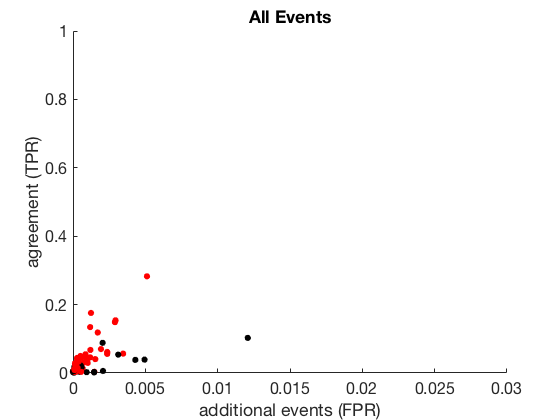

%% make the scatter plots


figure
for k = [1:21 25:72]
    markertype = rocDataAll(k).marker;
    if rocDataAll(k).treatment == 'KA'
        p1 = plot (rocDataAll(k).FPR,rocDataAll(k).TPR,[markertype '.'],...
            'MarkerFaceColor', 'r','MarkerSize',18);
    else
        p2 = plot (rocDataAll(k).FPR,rocDataAll(k).TPR,[markertype '.'],...
            'MarkerFaceColor', 'k','MarkerSize',18);
    end    
        hold on
end
    
xlabel('additional events (FPR)')
ylabel('agreement (TPR)')%,'FontSize',20)
title('All Events')
axis([0 0.03 0 1])
box off
xt = get(gca, 'XTick');
set(gca, 'FontSize', 16)
%legend([p1 p2], {'KA All', 'SA All'})

%savefig(gcf,'rocDataAll_SF5.fig')
saveas (gcf, 'rocDataAll_final.eps','epsc')

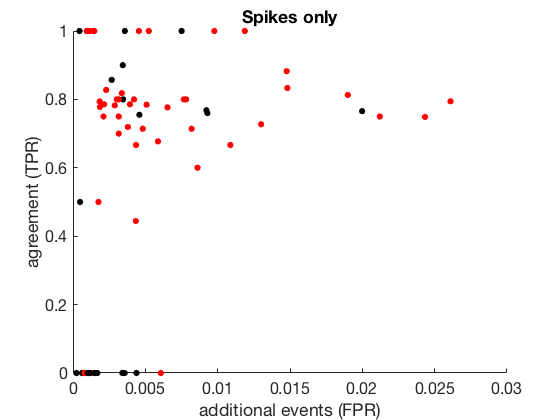


figure
for k = [1:21 25:72]
    markertype = rocDataAll(k).marker;
       
    if rocDataAll(k).treatment == 'KA'
        p3 = plot (rocDataSP(k).FPR,rocDataSP(k).TPR,[markertype '.'], 'MarkerSize',18);
    else
        p4 = plot (rocDataSP(k).FPR,rocDataSP(k).TPR,[markertype '.'],'MarkerSize',18);
    end
        hold on
end

xlabel('additional events (FPR)')
ylabel('agreement (TPR)')%,'FontSize',20)
title('Spikes only')
axis([0 0.03 0 1])
box off
xt = get(gca, 'XTick');
set(gca, 'FontSize', 16)
%legend([p3 p4], {'KA SP', 'SA SP'})

%savefig(gcf,'rocDataSP_SF5.fig')
saveas (gcf, 'rocDataSP_final.eps','epsc')



%adding up all the ROC data for all of the events

confMatAll = [0 0; 0 0];
confMatSP = [0 0; 0 0];

for k = [1:21 25:72]
    
    confMat = rocDataAll(k).confMatrix;
    confMatAll = confMatAll + confMat;
    
    clear confMat
    confMat = rocDataSP(k).confMatrix;
    confMatSP = confMatSP + confMat;
    
end

confMatAll

confMatAll =    1.0e+06 *
    0.0303    0.8330
    0.0059    5.0050

 confMatSP

confMatSP =    1.0e+06 *
    0.0035    0.0010
    0.0326    5.8371




    TPRall = confMatAll(1,1)/sum(confMatAll(1,:))

TPRall = 0.0350

    FPRall = confMatAll(2,1)/sum(confMatAll(2,:))

FPRall = 0.0012

    
    TPRsp = confMatSP(1,1)/sum(confMatSP(1,:))

TPRsp = 0.7775

    FPRsp = confMatSP(2,1)/sum(confMatSP(2,:))

FPRsp = 0.0056

   

    
    save('rocDataFigureData_SF4.mat','rocDataAll','rocDataSP',...
        'confMatSP', 'confMatAll','TPRall','FPRall','TPRsp',...
        'FPRsp')
%    clear TPRall TPRsp confMat confMatAll confMatSP...
%        p1 p2 p3 p4 tot xt h hh hj k m mm n nn nnn FPRall FPRsp...
%        rbEventSP 
%     
    

pulling out individual events: agrees, disagrees.

goal: individual events that jesse and i agree on, sorted according to how I classify the events, individual events that jesse finds but I don't, and individual events that I find but Jesse doesn't.


 fs = 512;
%for k = 1:72
 
for k = 2

k2str = num2str(k);
   
   
%pull pfammatter events from dataFrame (originally in datpoints, converted to seconds)
    
    a = dataFrame(k).starts;
    a = a';
    b = dataFrame(k).ends;
    b = b';
    evJP = floor([a b]/fs);
 
clear a b
    
%pull bergstrom events from SigSumm (originally in seconds, leave as seconds)
  
    %a1 = SigSumm(k).spike;
  %  a1 = a1*fs;
   a1= SigSumm(k).seizure;
   % a1 = SigSumm(k).abnormal;
    
    evRBsp = floor(a1);
%     evRBsz = floor(a2/fs); 
%     evRBabn = floor(a3/fs);
%     



if isempty(evRBsp) == 0
    
    clear a1 a2 a3;
    
     [m, ~] = size(evJP);
     [n, ~] = size(evRBsp);
     
% This loop pumps out a m x n (jp event# x rb event#) matrix
% with ONE (1) at the points where there is agreement. All
% other positions will be zeros. 

% For example: if jp event #2 is the same event as rb event #6, 
% there will be a one at position (2,6) in the matrix. 
    
      for mm = 1:m
     
                
        jpEvent = evJP(mm,1):evJP(mm,2); 
        jpEvent = jpEvent';
        %this is right.
         
        for nn = 1:n
           
             if mm == 1
                 h = 0;
             else end
             
                      
            rbEventSP = evRBsp(nn,1):evRBsp(nn,2);
            cSP = intersect (jpEvent,rbEventSP);
            
            if isempty(cSP)==1
                A(nn) = 0;
            else A(nn) = 1;
            end
            
            
               if nn == n && mm == 1
                evIDX = A;
                clear A
                elseif nn == n && mm ~= 1
                evIDX = [evIDX; A];
                clear A
               else
               end
            
            
        end
      
      end
      
      
     
      % this is the final index of agreement for this event type! 
  [jesse, rachel] = find(evIDX);
      
 clear evIDX evJP evRBsp jpEvent m mm n nn rbEventSP cSP

fileID = SigSumm(k).fileID;
EEG = dataFrame(k).signal;

a = dataFrame(k).starts;
a = a';
b = dataFrame(k).ends;
b = b';

%a1 = SigSumm(k).spike;
a1 = SigSumm(k).seizure;
%a1 = SigSumm(k).abnormal;
a1 = a1*fs;

p = length(jesse);
totSpikeAgree(k) = p;

%for final figure, use these values

% pRow = 3;
% pCol = 3;


%for quick test, use these values
pRow = 4;
pCol = 2;

jpPlot = [];
for pp = 1:p
  jpPlot = [jpPlot a(jesse(pp)):b(jesse(pp))];   
end



      for pp = 1:p %change as needed to replot events
                         
        n = ceil(pp/(pRow*pCol))- 1;
        nn = (pRow*pCol)*n;
        mm = pp - nn; 
        
   
          
          rbPlot = a1(rachel(pp),1):a1(rachel(pp),2);
          jpPlot = a(jesse(pp)):b(jesse(pp));
%        jpPlotStart = a(jesse(pp)):b(jesse(pp));
           wholePlot = jpPlot(1)-(fs*10):jpPlot(1)+fs*10;
  %     wholePlot = jpPlotStart(1)-(fs*10):jpPlotStart(1)+fs*10;
          
         % XMIN = jpPlotStart(1)/fs - 1;
         % XMAX = jpPlotStart(1)/fs + 10;
           XMIN = jpPlot(1)/fs - 1;
          XMAX = jpPlot(1)/fs + 10;
          YMIN = -15;
          YMAX = 15;
          
          subplot (pRow, pCol, mm)
          plot(wholePlot/fs,EEG(wholePlot),'k', 'LineWidth',0.25)
          hold on
          plot (rbPlot/fs, EEG(rbPlot),'k','LineWidth',0.75)
          plot(jpPlot/fs, EEG(jpPlot),'r','LineWidth',1.0)
          
                 
           axis([XMIN XMAX YMIN YMAX])
               box off
               %for figure, leave axes on
              if p > 2
               axis off
              else end
               
               
         
           mStr = num2str (pp);
          if mm == pRow*pCol || pp == p
                    
                   saveas(gcf, [k2str '_' fileID 'sz_' mStr '.eps'], 'epsc')
                   close (gcf)
                   
               else 
               end
      
               
        clear n nn mm rbPlot jpPlot XMIN XMAX...
            YMIN YMAX mStr
      end
    
      clear a a1 b EEG jesse rachel p pCol pRow
   
      
else 
    fileID = SigSumm(k).fileID;
    plot (0,0,'r*','Markersize',50)
    title (fileID)
    axis ([-1 1 -1 1])
    
    totSpikeAgree(k) = 0; 
    saveas(gcf, [ k2str '_' fileID 'sz_NOAGREEMENT.eps'], 'epsc')
                   close (gcf)
end


clear fileID k2str pp
  end
 
      spikeAgreement = sum(totSpikeAgree)

spikeAgreement = 1281